clear variables

num=[2 5];
den = conv([1 5 6],[1 2 5]);
H = tf(num, den)

H =
 
              2 s + 5
  --------------------------------
  s^4 + 7 s^3 + 21 s^2 + 37 s + 30
 
Continuous-time transfer function.



zpk(H)

ans =
 
          2 (s+2.5)
  --------------------------
  (s+2) (s+3) (s^2 + 2s + 5)
 
Continuous-time zero/pole/gain model.



[R,P,R_inf] = residue(num,[den 0])

R =   -0.0417 + 0.0000i
  -0.0125 + 0.0875i
  -0.0125 - 0.0875i
  -0.1000 + 0.0000i
   0.1667 + 0.0000i


P =   -3.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -2.0000 + 0.0000i
   0.0000 + 0.0000i



R_inf =

     []



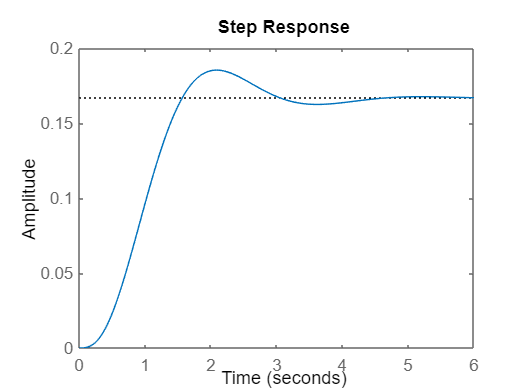

step(H)


syms s;
t1 = ilaplace(R(1)/(s-P(1)))

$$t1 = -\frac{{\mathrm{e}}^{-3\,t}}{24}$$

t2 = ilaplace(R(2)/(s-P(2)))

$$t2 = {\mathrm{e}}^{t\,\left(-1+2\,\mathrm{i}\right)}\,\left(-\frac{1}{80}+\frac{7}{80}\,\mathrm{i}\right)$$

t3 = ilaplace(R(4)/(s-P(4)))

$$t3 = -\frac{{\mathrm{e}}^{-2\,t}}{10}$$

t4 = ilaplace(R(5)/(s-P(5)))

$$t4 = \frac{1}{6}$$

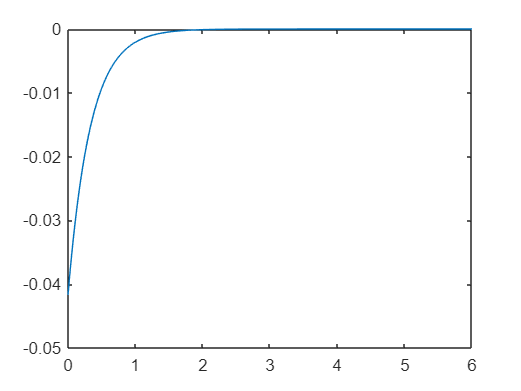


clear variables
ti = 6;
t = linspace(0,ti,1000);
figure,

plot(t,-exp(-3*t)/24);

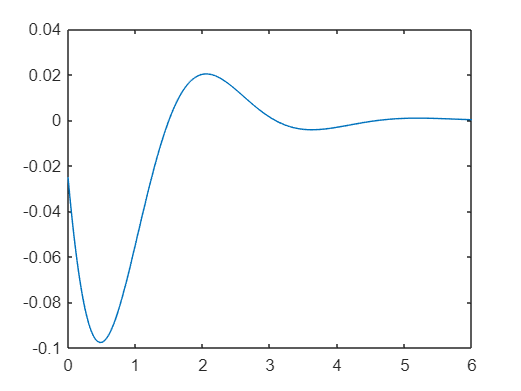

plot(t,-exp(-t).*(cos(2*t)+7*sin(2*t))/40)

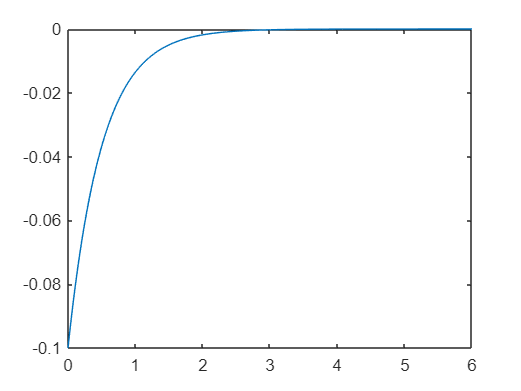

plot(t,-exp(-2*t)/10)

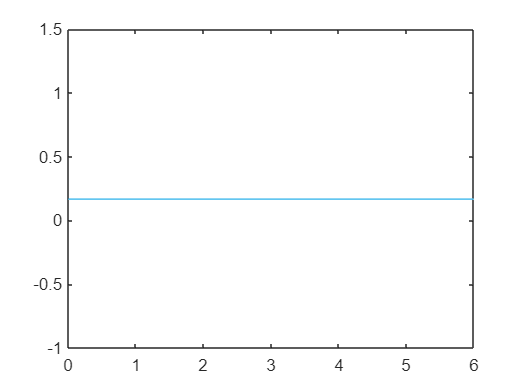

plot(t,1/6*ones(1000))